# Lab 1: Sampled-Data Systems are Different

Pranshu Malik (`1004138916`) and Varun Sampat (`1003859602`)

In this lab we explore how the discretization can result in different <>... Continuous-time (CT) systems and Discrete-time (DT) systems, particularly linear time-invariant (LTI) systems. We will start with exploring CT systems to DT through sampling. Sampling Continuous Time Signals. after which we will do <part 2>, followed by <part 3>.

## 1. Aliasing

Consider the CT LTI plant with transfer function $G(s) = \frac{1}{s^2 + 0.8s + 1}$. Plot $||G(j\Omega)||$ and $\angle G(j\Omega)$ over frequencies: $\Omega \in (0, 6]  \text{ [rad/s]}$. 

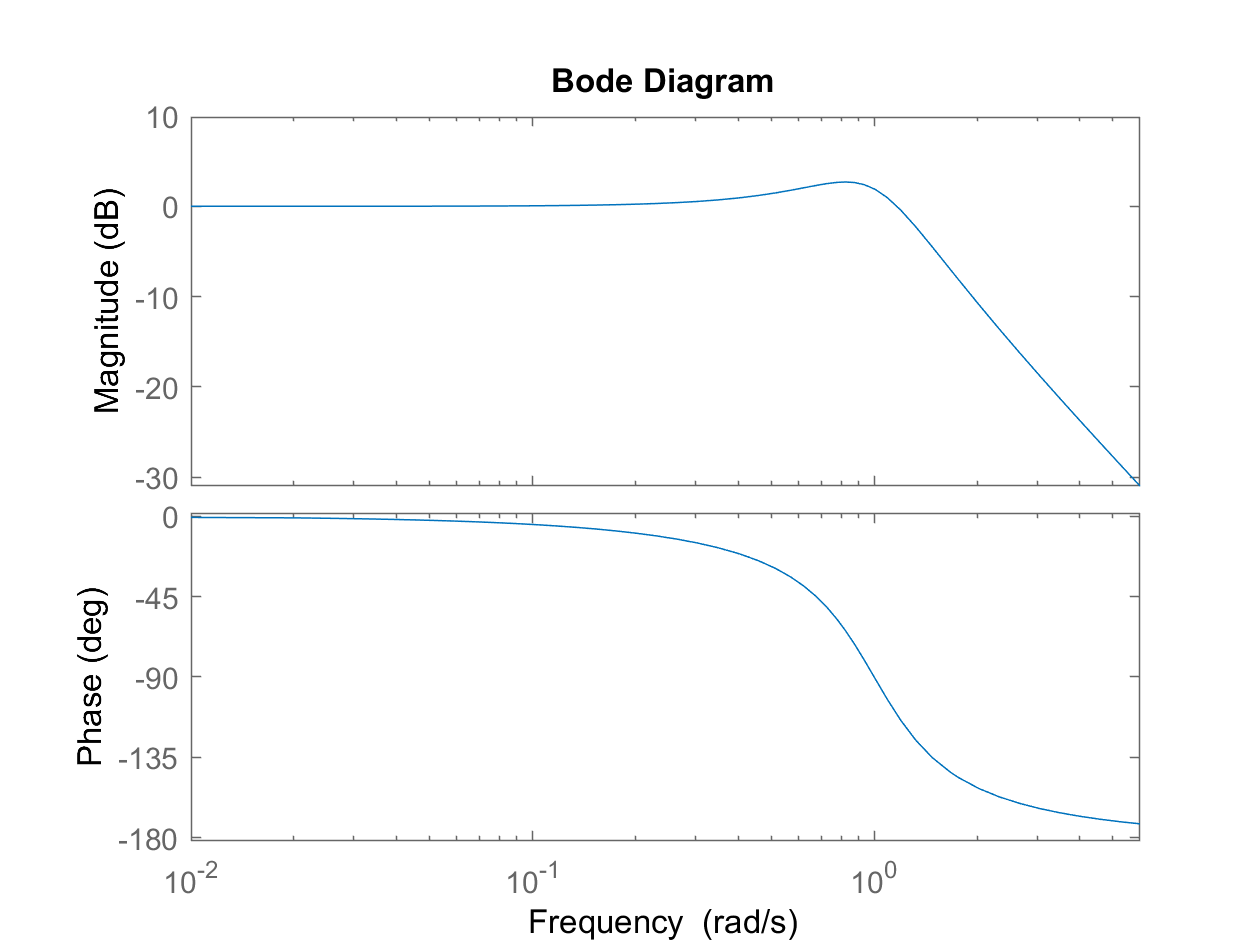

Gs = tf(1, [1 0.8 1]); % plant transfer function
bode(Gs, {0, 6});      % bode plot of G(s)

Now, we sample the $g(t)$ to get $g(kT_s)$ where $T_s$ is the sampling interval. Then, we get: $G(e^{j\omega}) = \frac{1}{T_s}\sum_k G\left( j \left(\frac{\omega}{T_s}-\frac{2\pi k}{T_s}\right)\right)$ where $G(j\Omega)$ is the CTFT of impulse response $g(t)$ and $\omega \text{ [rad]} = \Omega \text{ [rad/s] } T_s$ is the normalized angular frequency.

TODO: need to compute G(z) and write it here. How to do? Check notes.

% sample the CT impulse response of the plant to get its DTFT
Ts = 1;
Gz = c2d(Gs, Ts, 'impulse')


Gz =
 
   0.5803 z - 3.222e-17
  -----------------------
  z^2 - 0.8159 z + 0.4493
 
Sample time: 1 seconds
Discrete-time transfer function.



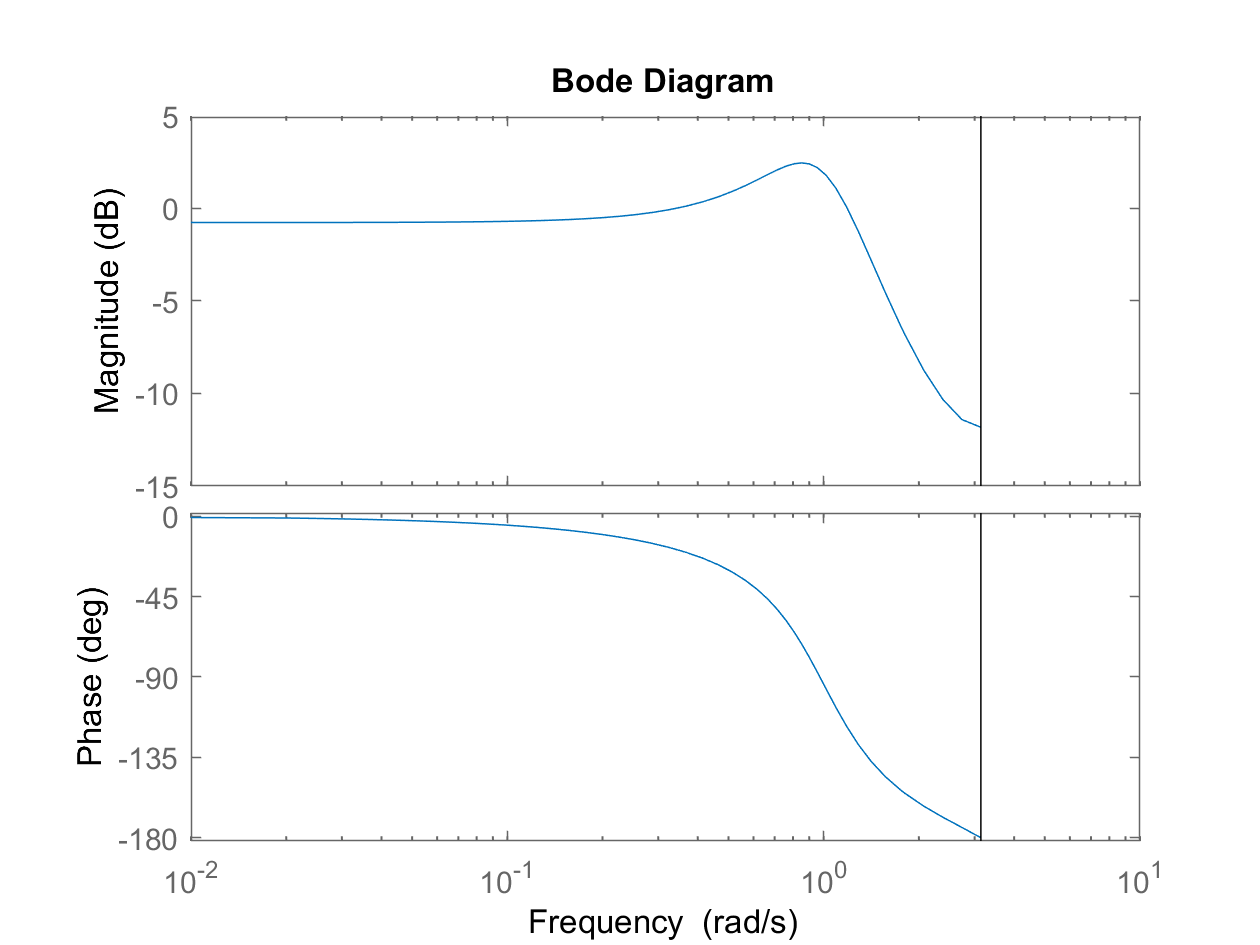

dbode(Gz, Ts, {0, 10});

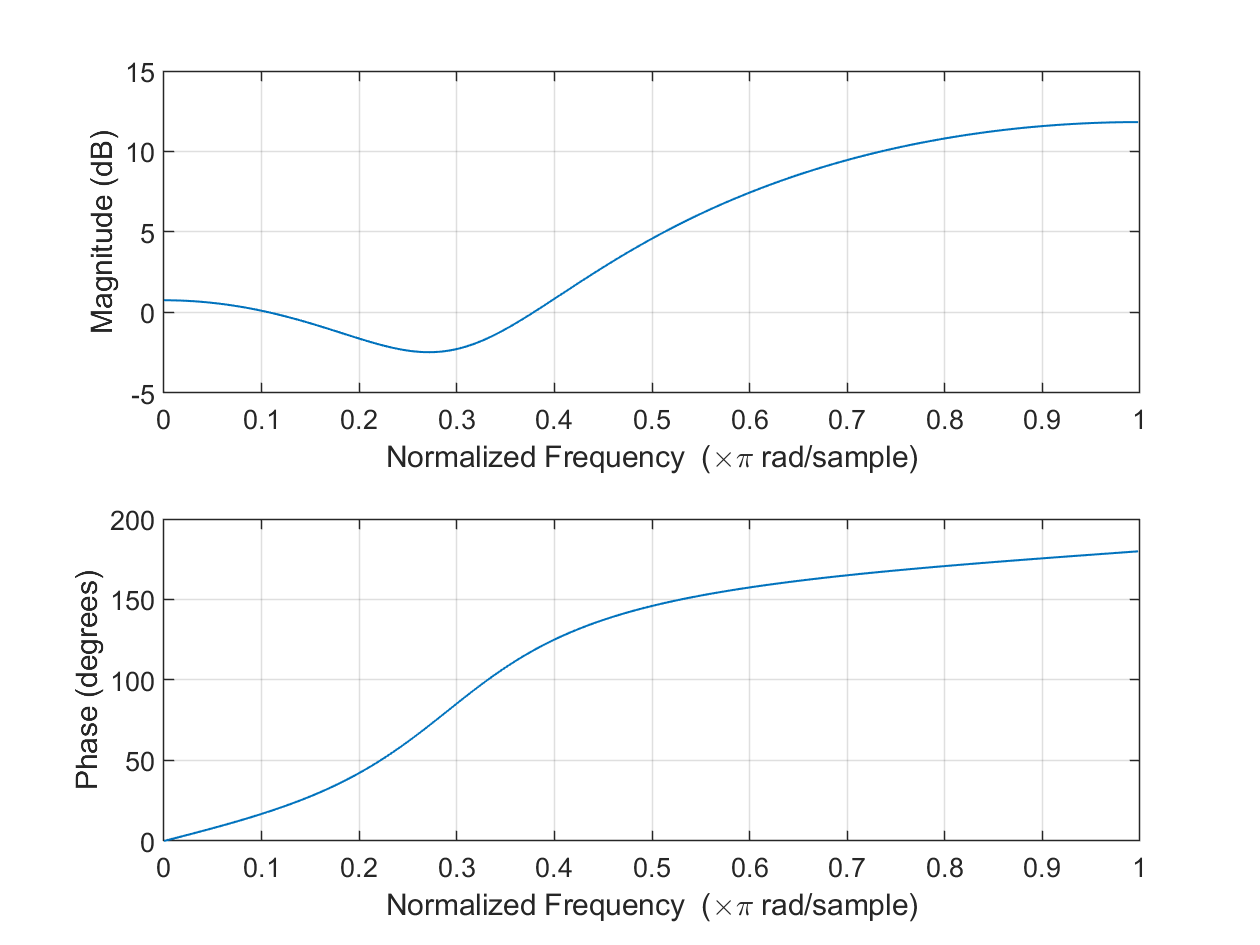

freqz(Gz.Denominator{:}, Gz.Numerator{:})

## 2. Effects of Sample and Hold on Control Design

## 3. Intersample Ripple